### Example dataset is provided. It is an EEG recording with 60 channels (i.e., electrodes) to discriminate between face versus car trials. 

% Load example dataset
% Two subjects and two conditions are included.
clc
clear
load("sub1_Car.mat")
load("sub2_Car.mat")
load("sub1_Face.mat")
load("sub2_Face.mat")

Sample rate of example dataset is 1000. The dataset matrix is structured as channels*sample points (times)*trials, where channels number is 69, times is 1.2s (1200 sample points where the first 200 points are before the simuli), and trail number is around 35. 

% Electrode 1 (FP1), 4 (F7), 5 (F3) is chosen as ROI (left-prefrontal)
ix_chan_select = [1,4,5];
% Calculate ITPC for the given ROI
itpc_car_sub1 = itpc(sub1_EEG_Car,ix_chan_select);
itpc_face_sub1 = itpc(sub1_EEG_Face,ix_chan_select);
itpc_car_sub2 = itpc(sub2_EEG_Car,ix_chan_select);
itpc_face_sub2 = itpc(sub2_EEG_Face,ix_chan_select);

Plot the output.

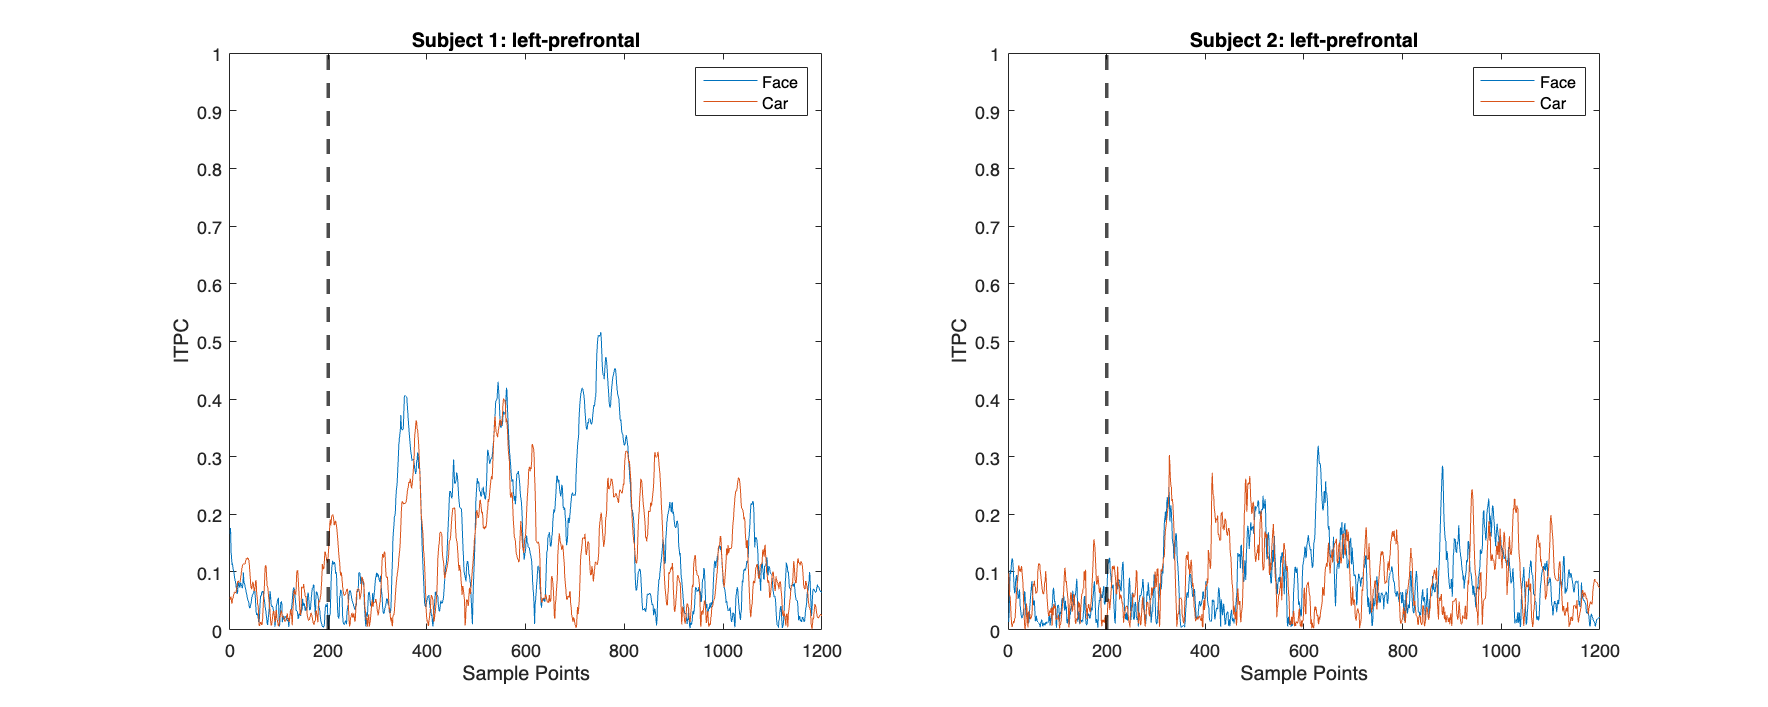

figure('Position', [100, 100, 1000, 400]); % [left, bottom, width, height]
clf
subplot(121)
plot(itpc_face_sub1)
hold on
plot(itpc_car_sub1)
xline(200,'k--','LineWidth',2)
legend('Face','Car')
title('Subject 1: left-prefrontal')
ylabel('ITPC')
xlabel('Sample Points')
ylim([0,1])
subplot(122)
plot(itpc_face_sub2)
hold on
plot(itpc_car_sub2)
xline(200,'k--','LineWidth',2)
legend('Face','Car')
title('Subject 2: left-prefrontal')
ylabel('ITPC')
xlabel('Sample Points')
ylim([0,1])

% Calculate ITPC across all electrodes
itpc_car_sub1 = itpc(sub1_EEG_Car);

No ROI specified, so all electrodes will be used.


itpc_face_sub1 = itpc(sub1_EEG_Face);

No ROI specified, so all electrodes will be used.


itpc_car_sub2 = itpc(sub2_EEG_Car);

No ROI specified, so all electrodes will be used.


itpc_face_sub2 = itpc(sub2_EEG_Face);

No ROI specified, so all electrodes will be used.


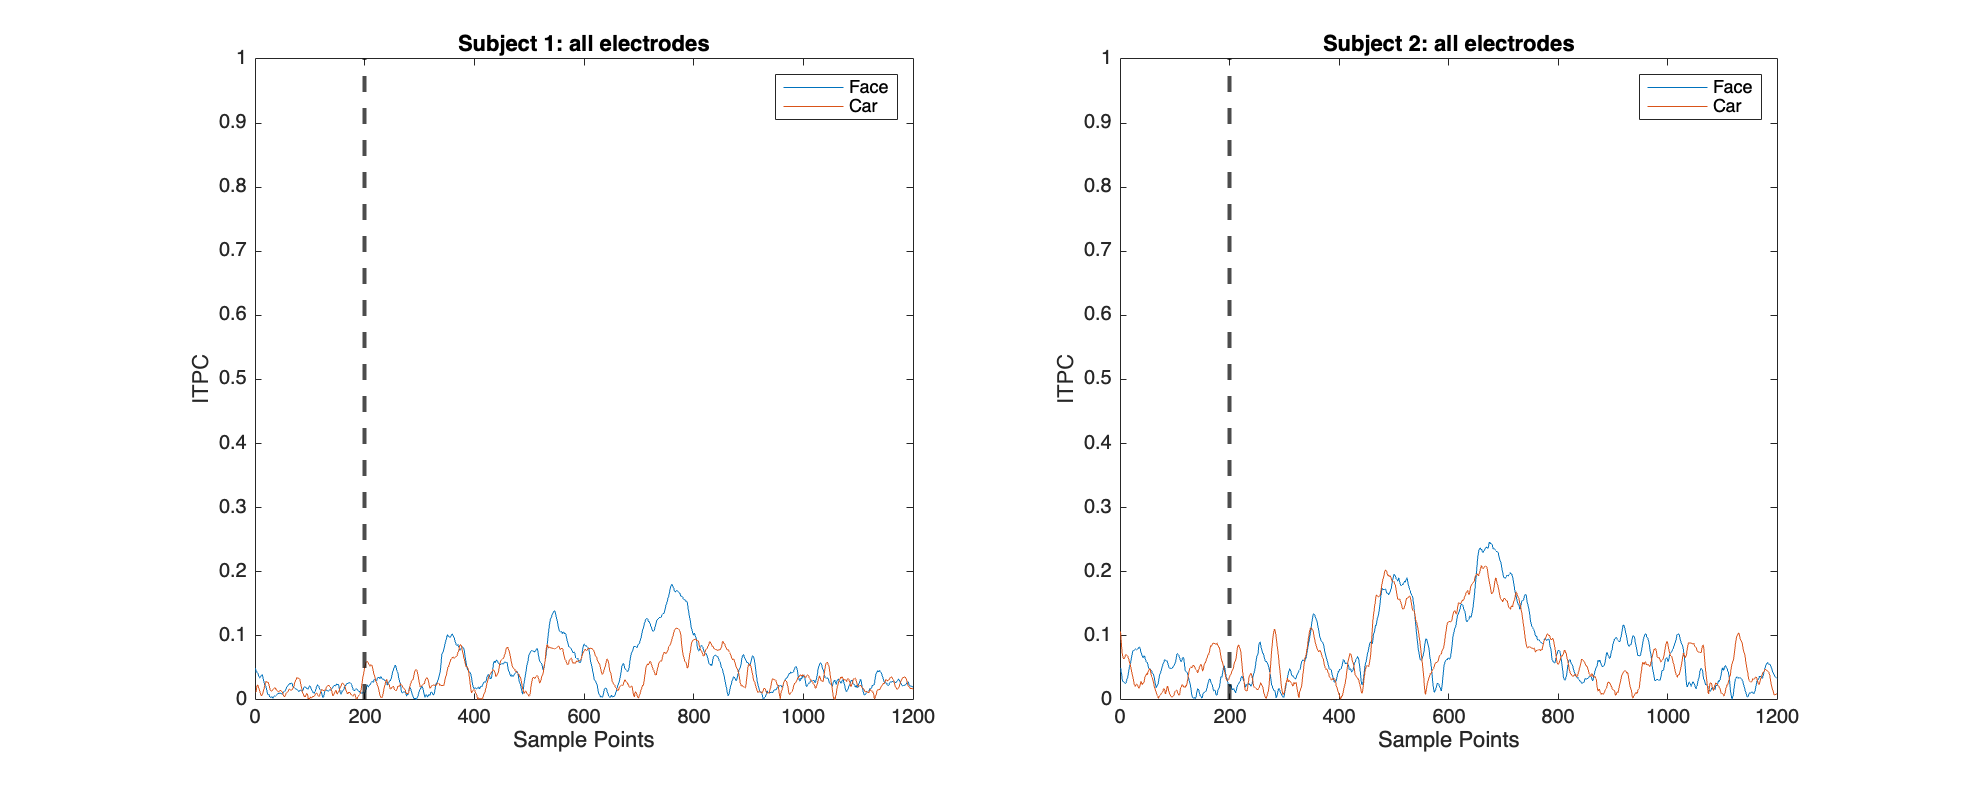

figure('Position', [100, 100, 1000, 400]); % [left, bottom, width, height]
clf
subplot(121)
plot(itpc_face_sub1)
hold on
plot(itpc_car_sub1)
xline(200,'k--','LineWidth',2)
legend('Face','Car')
title('Subject 1: all electrodes')
ylabel('ITPC')
xlabel('Sample Points')
ylim([0,1])
subplot(122)
plot(itpc_face_sub2)
hold on
plot(itpc_car_sub2)
xline(200,'k--','LineWidth',2)
legend('Face','Car')
title('Subject 2: all electrodes')
ylabel('ITPC')
xlabel('Sample Points')
ylim([0,1])

### Compare the result with trial-weighted ITPC, where we use the pre-stimuli 0.2s (200 time points) for trial-weight calculation. 

% Target for alpha band
alpha_band = [8,14];
total_band = [1,30];
srate = 1000;
% Calculate the relative power and generate weight on a region-level
% now only the pre onset eeg data was used to calculate trial weights (varied by study) 
eeg_post_sub1_car = sub1_EEG_Car(:,201:end,:);
eeg_pre_sub1_car = sub1_EEG_Car(:,1:200,:);
trial_weights_region = trial_weight_power(eeg_pre_sub1_car,srate,alpha_band,total_band,ix_chan_select);
witpc_car_sub1 = witpc(trial_weights_region,eeg_post_sub1_car,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


% Subject 1 Face
eeg_post_sub1_face = sub1_EEG_Face(:,201:end,:);
eeg_pre_sub1_face = sub1_EEG_Face(:,1:200,:);
trial_weights_region = trial_weight_power(eeg_pre_sub1_face,srate,alpha_band,total_band,ix_chan_select);
witpc_face_sub1 = witpc(trial_weights_region,eeg_post_sub1_face,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


% same for subject 2 
eeg_post_sub2_car = sub2_EEG_Car(:,201:end,:);
eeg_pre_sub2_car = sub2_EEG_Car(:,1:200,:);
trial_weights_region = trial_weight_power(eeg_pre_sub2_car,srate,alpha_band,total_band,ix_chan_select);
witpc_car_sub2 = witpc(trial_weights_region,eeg_post_sub2_car,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


% Subject 2 Face
eeg_post_sub2_face = sub2_EEG_Face(:,201:end,:);
eeg_pre_sub2_face = sub2_EEG_Face(:,1:200,:);
trial_weights_region = trial_weight_power(eeg_pre_sub2_face,srate,alpha_band,total_band,ix_chan_select);
witpc_face_sub2 = witpc(trial_weights_region,eeg_post_sub2_face,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


% Calculate ITPC for the given ROI
itpc_car_sub1 = itpc(sub1_EEG_Car,ix_chan_select);
itpc_face_sub1 = itpc(sub1_EEG_Face,ix_chan_select);
itpc_car_sub2 = itpc(sub2_EEG_Car,ix_chan_select);
itpc_face_sub2 = itpc(sub2_EEG_Face,ix_chan_select);

### Plot the witpc and itpc for comparison.

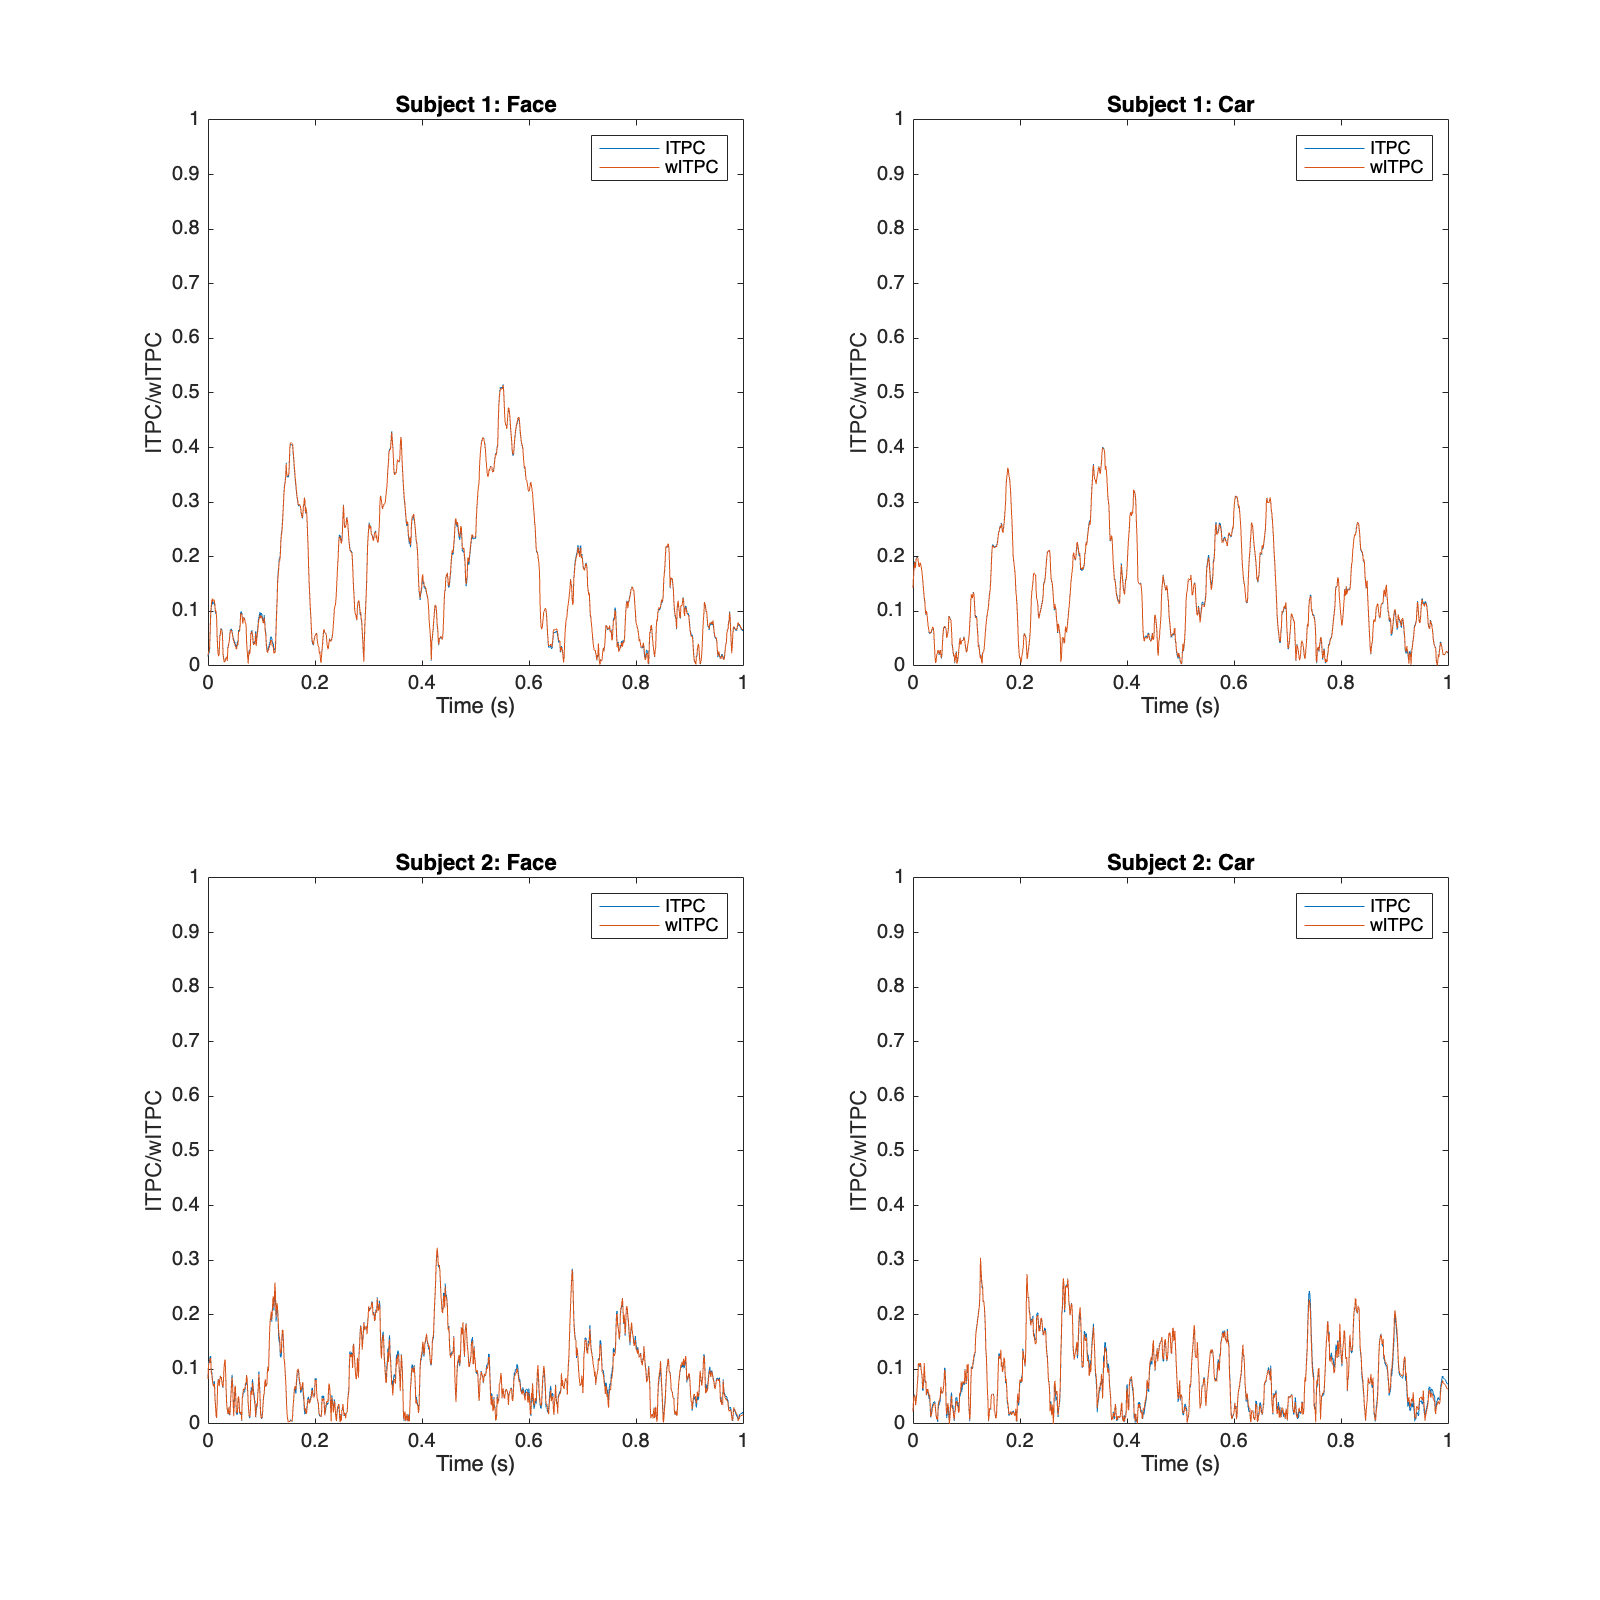

figure('Position', [100, 100, 1000, 1000]); % [left, bottom, width, height]
clf
subplot(221)
% Plot from the onset
plot(linspace(0,1,srate),itpc_face_sub1(201:end))
hold on
plot(linspace(0,1,srate),witpc_face_sub1)
legend('ITPC','wITPC')
title('Subject 1: Face')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(222)
plot(linspace(0,1,srate),itpc_car_sub1(201:end))
hold on
plot(linspace(0,1,srate),witpc_car_sub1)
legend('ITPC','wITPC')
title('Subject 1: Car')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(223)
% Plot from the onset
plot(linspace(0,1,srate),itpc_face_sub2(201:end))
hold on
plot(linspace(0,1,srate),witpc_face_sub2)
legend('ITPC','wITPC')
title('Subject 2: Face')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(224)
plot(linspace(0,1,srate),itpc_car_sub2(201:end))
hold on
plot(linspace(0,1,srate),witpc_car_sub2)
legend('ITPC','wITPC')
title('Subject 2: Car')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

### Since pre-stimuli 0.2s (200 time points) alpha power is very similar across trials, no significant difference between ITPC and wITPC. 

% now only the post onset eeg data was used (varied by study) 
trial_weights_region = trial_weight_power(eeg_post_sub1_car,srate,alpha_band,total_band,ix_chan_select);
witpc_car_sub1 = witpc(trial_weights_region,eeg_post_sub1_car,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


trial_weights_region = trial_weight_power(eeg_post_sub1_face,srate,alpha_band,total_band,ix_chan_select);
witpc_face_sub1 = witpc(trial_weights_region,eeg_post_sub1_face,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


% same for subject 2 
trial_weights_region = trial_weight_power(eeg_post_sub2_car,srate,alpha_band,total_band,ix_chan_select);
witpc_car_sub2 = witpc(trial_weights_region,eeg_post_sub2_car,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


trial_weights_region = trial_weight_power(eeg_post_sub2_face,srate,alpha_band,total_band,ix_chan_select);
witpc_face_sub2 = witpc(trial_weights_region,eeg_post_sub2_face,ix_chan_select);

The given trial weights are region-level average(or include only 1 electrodes).


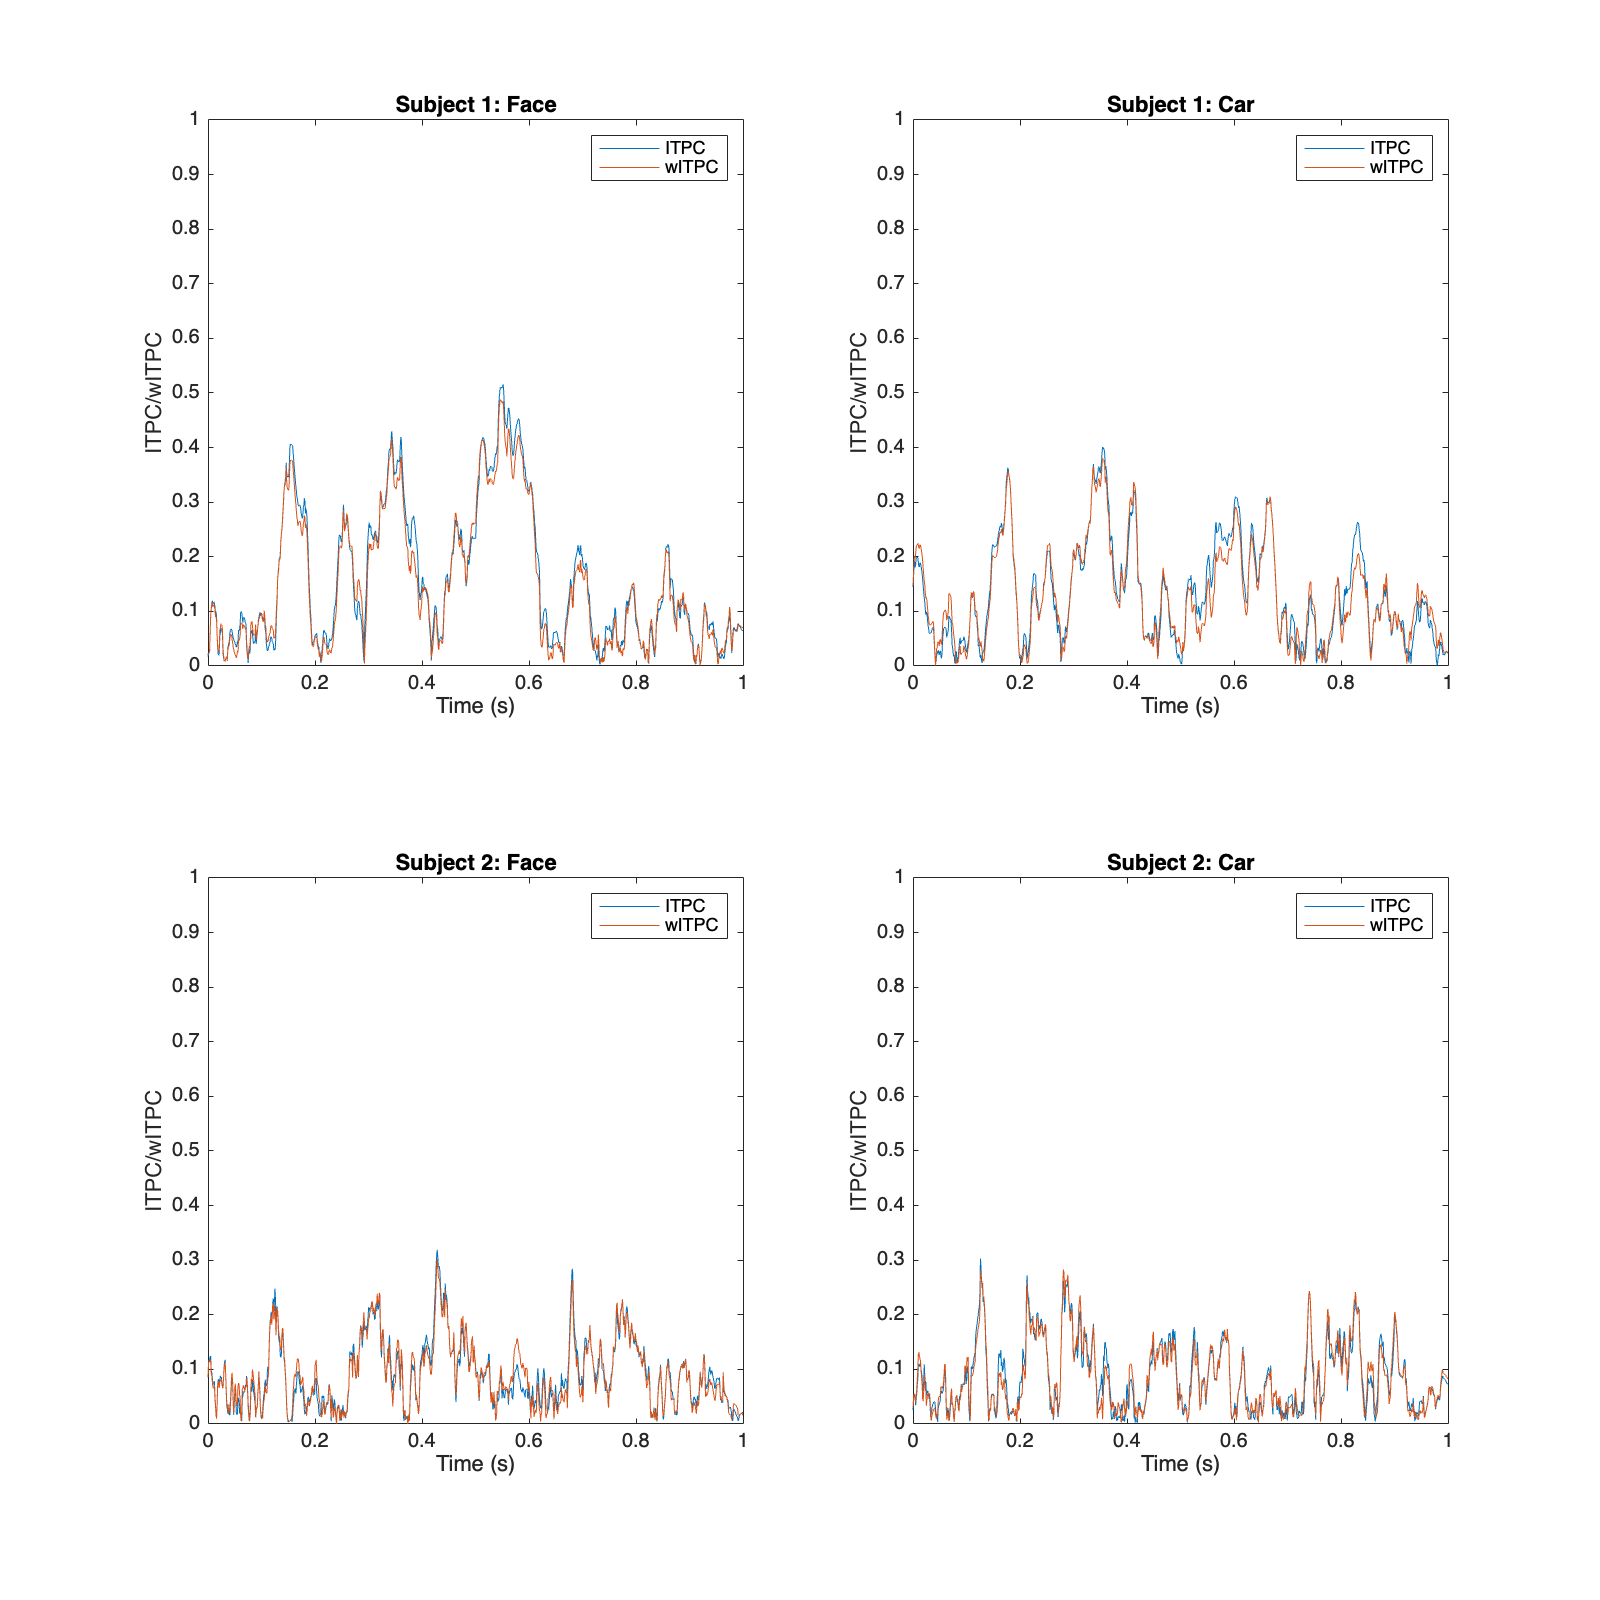

figure('Position', [100, 100, 1000, 1000]); % [left, bottom, width, height]
clf
subplot(221)
% Plot from the onset
plot(linspace(0,1,srate),itpc_face_sub1(201:end))
hold on
plot(linspace(0,1,srate),witpc_face_sub1)
legend('ITPC','wITPC')
title('Subject 1: Face')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(222)
plot(linspace(0,1,srate),itpc_car_sub1(201:end))
hold on
plot(linspace(0,1,srate),witpc_car_sub1)
legend('ITPC','wITPC')
title('Subject 1: Car')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(223)
% Plot from the onset
plot(linspace(0,1,srate),itpc_face_sub2(201:end))
hold on
plot(linspace(0,1,srate),witpc_face_sub2)
legend('ITPC','wITPC')
title('Subject 2: Face')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

subplot(224)
plot(linspace(0,1,srate),itpc_car_sub2(201:end))
hold on
plot(linspace(0,1,srate),witpc_car_sub2)
legend('ITPC','wITPC')
title('Subject 2: Car')
ylabel('ITPC/wITPC')
xlabel('Time (s)')
ylim([0,1])

### When using the post-stimuli 1s (1000 time points) for trial-weight calculation, some difference can be observed (especially the peaks are different). 